# `LAB2：线性时不变系统（2.4 与 2.10）`

`朱泺源 12511622 罗玛 12510925`

`实验目标概括：`

`先验证卷积的几条运算规律，再将 LTI 系统用于回声录音。2.10(a-e) 用已知回声模型恢复语音；2.10(f) 用新的录音估计未知的 N 和 alpha。`

`具体实验内容：`

`一、2.4：卷积性质验证`

`(1)题目解析`

`离散 LTI 系统的输出可以用卷积求出。课件介绍了交换律、分配律、结合律。这里选用有限序列，分别用两种顺序计算，看看结果是否相同。`

`(2)程序代码`

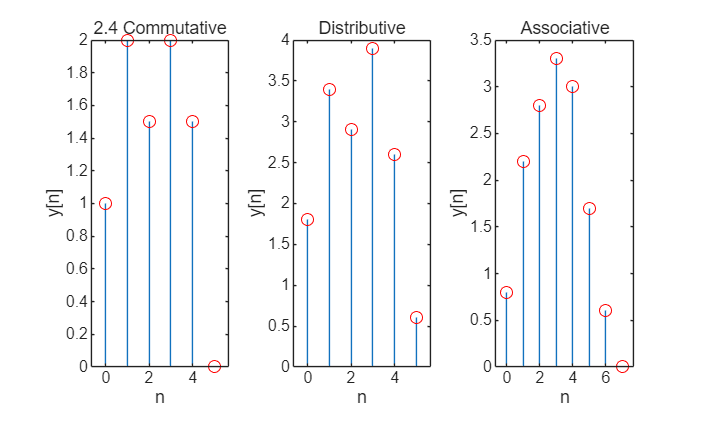

% 2.4 卷积性质
x1 = [1 1 0.5 1.5];
h1 = [1 1 0];
h2 = [0.8 0.6 0.4];

a = conv(x1,h1);  b = conv(h1,x1);
c = conv(x1,h1+h2);  d = conv(x1,h1)+conv(x1,h2);
e = conv(conv(x1,h1),h2);  f = conv(x1,conv(h1,h2));

figure
tiledlayout(1,3,'Padding','loose','TileSpacing','loose')
nexttile; stem(0:length(a)-1,a); hold on; plot(0:length(b)-1,b,'ro'); title('2.4 Commutative'); xlabel('n'); ylabel('y[n]')
nexttile; stem(0:length(c)-1,c); hold on; plot(0:length(d)-1,d,'ro'); title('Distributive'); xlabel('n'); ylabel('y[n]')
nexttile; stem(0:length(e)-1,e); hold on; plot(0:length(f)-1,f,'ro'); title('Associative'); xlabel('n'); ylabel('y[n]')

`(3)结果图`

`三幅 stem 图分别对应交换、分配和结合律。圈出的第二组数据与第一组样本重合。`

`(4)结果分析`

`三幅图中，两种计算方式得到的结果都重合。串联系统也可以先把两个系统的冲激响应卷积，再计算输出。`

`二、2.10(a)-(e)：已知回声系统与逆滤波`

`(1)题目解析`

`已知接收语音 y[n] = x[n]+0.5x[n-1000]，相当于原声和延迟 1000 点、幅度变为 0.5 的副本相加。所以 h_e[n] = delta[n]+0.5delta[n-1000]。由这个方程反解可得 x[n] = y[n]-0.5x[n-1000]，在零初始状态下用 filter 递推即可。`

`(2)程序代码`

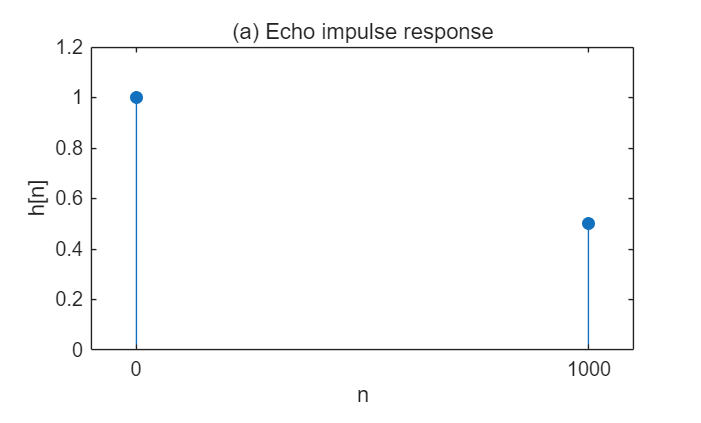

load('lineup.mat','y');
h = [1 zeros(1,999) 0.5];

% (a) Echo impulse response
figure; tiledlayout(1,1,'Padding','loose'); nexttile; stem([0 1000],[h(1) h(end)],'filled'); xlim([-100 1100]); ylim([0 1.2]); xticks([0 1000]); title('(a) Echo impulse response'); xlabel('n'); ylabel('h[n]');

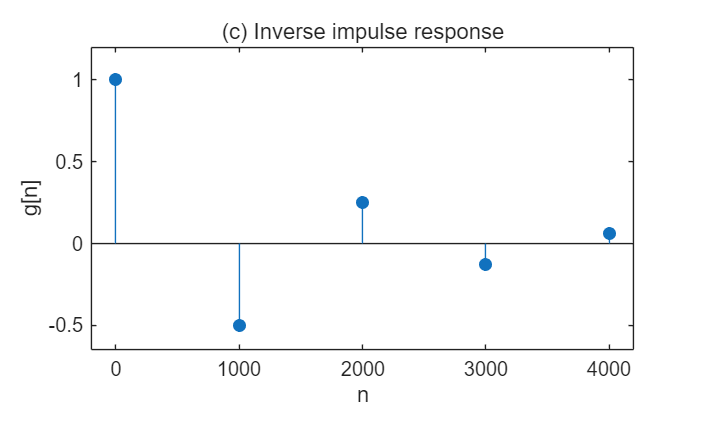


% (b)(c) Inverse system
g = filter(1,h,[1 zeros(1,4000)]);
figure; tiledlayout(1,1,'Padding','loose'); nexttile; stem(0:1000:4000,g(1:1000:end),'filled'); xlim([-200 4200]); ylim([-0.65 1.2]); xticks(0:1000:4000); title('(c) Inverse impulse response'); xlabel('n'); ylabel('g[n]');

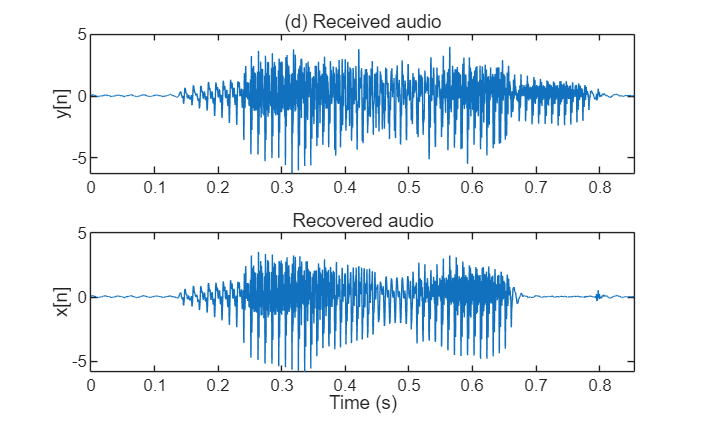


% (d) Recover the original audio
x = filter(1,h,y);
t = (0:length(y)-1)/8192;
figure
tiledlayout(2,1,'Padding','loose','TileSpacing','loose')
nexttile; plot(t,y); title('(d) Received audio'); ylabel('y[n]'); xlim([t(1) t(end)])
nexttile; plot(t,x); title('Recovered audio'); xlabel('Time (s)'); ylabel('x[n]'); xlim([t(1) t(end)])

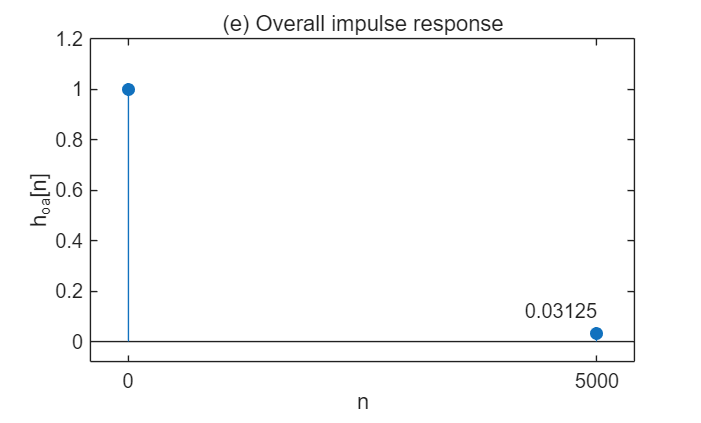


% (e) Cascaded impulse response
h_total = conv(h,g);
figure; tiledlayout(1,1,'Padding','loose'); nexttile; stem([0 5000],[h_total(1) h_total(end)],'filled');
xlim([-400 5400]); ylim([-0.08 1.2]); xticks([0 5000]);
text(5000,0.12,'0.03125','HorizontalAlignment','right');
title('(e) Overall impulse response'); xlabel('n'); ylabel('h_{oa}[n]');

`(3)结果图`

`回声响应有两个脉冲；逆响应每隔 1000 点出现一个幅度逐渐减小、正负交替的脉冲。逆滤波后能看到语音波形发生变化。串联系统总体响应在 n=0 处为 1，有限长度截断在 n=5000 处还会留下 0.03125。`

`(4)结果分析`

`通过 x[n]=y[n]-0.5x[n-1000] 逐点恢复原声。逆系统的冲激响应是无限长的，图中只画前 4001 点，因此串联后的冲激响应仍留有很小的尾部。`

`三、2.10(f)：估计新录音的回声参数`

`(1)题目解析`

`新数据在 lineup_n.mat 中，y_n 是新的带回声录音。设 y_n[n]=x[n]+alpha*x[n-N]。先求 r[n]=y_n[n]-x[n]，再计算 r 和 x 的互相关，相关峰的位置就是回声延迟 N。最后比较对应的信号幅度，求出 alpha。没有把结果提前写成固定参数。`

`(2)程序代码`

load('lineup_n.mat','y_n','fs');
r = y_n - x;
c = conv(r,flipud(x));
[~,N] = max(abs(c(length(x)+1:end)));
alpha = (x(1:end-N)'*r(N+1:end))/(x(1:end-N)'*x(1:end-N));
fprintf('N = %d, alpha = %.2f, delay = %.5f s\n',N,alpha,N/double(fs));

N = 1250, alpha = 0.70, delay = 0.15625 s


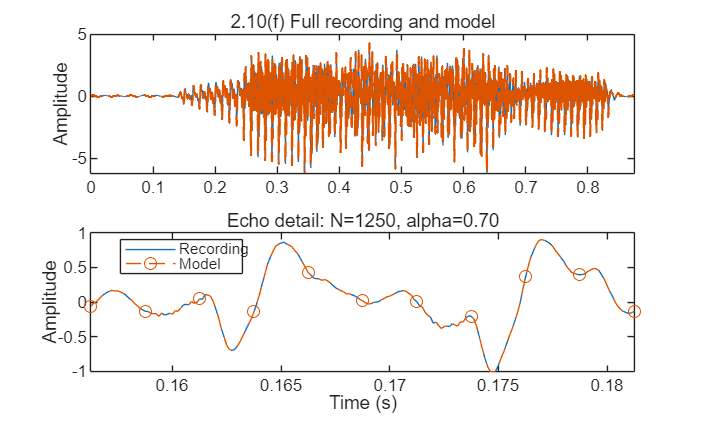


t = (0:length(y_n)-1)/double(fs);
y_model = x + alpha*[zeros(N,1);x(1:end-N)];
figure
tiledlayout(2,1,'Padding','loose','TileSpacing','loose')
nexttile; plot(t,y_n); hold on; plot(t,y_model,'--','LineWidth',1.1);
title('2.10(f) Full recording and model'); ylabel('Amplitude'); xlim([t(1) t(end)])
nexttile; k = find(t >= N/double(fs) & t <= N/double(fs)+0.025);
plot(t(k),y_n(k)); hold on;
plot(t(k),y_model(k),'--o','MarkerIndices',1:20:length(k));
title(sprintf('Echo detail: N=%d, alpha=%.2f',N,alpha));
xlabel('Time (s)'); ylabel('Amplitude'); xlim([t(k(1)) t(k(end))]);
legend('Recording','Model','Location','best');

`(3)结果图`

`将求出的 N 和 alpha 代回单回声模型，图中模型输出与新录音基本重合。`

`(4)结果分析`

`得到 N=1250、alpha=0.7；采样率 fs=8000 Hz，所以回声延迟为 0.15625 s。将这两个参数代回后，重建波形与录音相吻合。`

`经验总结：`

`@朱泺源>在 2.4 中我发现卷积可以换一种顺序计算，串联时先合并系统比较方便；到 2.10 就能用同一个方法检查整个回声系统。`

`@罗玛>做逆滤波时要看清楚延迟和数组长度。估计回声参数以后最好代回原方程，不能只看自相关的一个峰。`

`自我评价：`

`@朱泺源 10`

`@罗玛 10`